# SLCO4A - Aula Prática 5

## Sistemas

### Classificação de sistemas

#### SISO - Single-Input Single-Output 

a) A relação que descreve um sistema S é $y\left(t\right)=x\left(t-2\right)$. Compute e plot a resposta do sistema para um sinal de entrada $x\left(t\right)=\textrm{tcos}\left(2\pi \;t\right)$, $0\le t\le 3$.

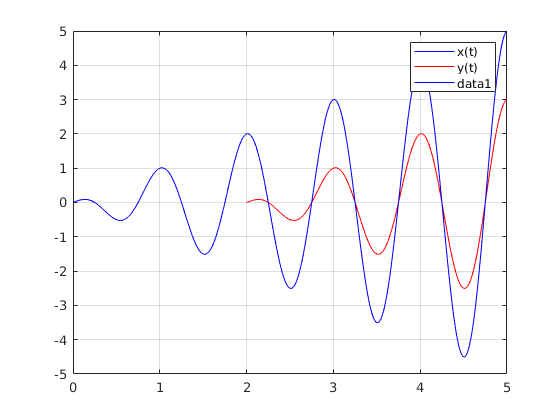

t=0:0.01:3;
x=t.*cos(2*pi*t);
plot(t,x,'b')
hold on
plot (t+2,x,'r')
legend('x(t)', 'y(t)')
grid on

t=0:0.01:5;
x=t.*cos(2*pi*t);
plot(t,x,'b')


for i=1: length(t)
    if t(i) <=2
    y(1,i)=0;
    else
    y(1,i) = (t(i)-2).*cos(2*pi*t(i)-2);
    end
end
figure
%plot (t,x,'b', t, y, 'r')
legend('x(t)', 'y(t)')

grid on


#### MISO - Multiple-Input Single-Output 

b) Suponha que um sistema MISO S  é descrito pela relação entrada saída $y\left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)x_3 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)-u\left(t-3\right)$, $x_2 \left(t\right)=t\;\sin \left(t\right)$ e $x_3 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

t=0:0.01:4;
x1=heaviside(t)- heaviside(t-3);
x2= t.*sin(t)

x2 =          0    0.0001    0.0004    0.0009    0.0016    0.0025    0.0036    0.0049    0.0064    0.0081    0.0100    0.0121    0.0144    0.0169    0.0195    0.0224    0.0255    0.0288    0.0322    0.0359    0.0397    0.0438    0.0480    0.0524    0.0570    0.0619    0.0668    0.0720    0.0774    0.0829    0.0887    0.0946    0.1007    0.1069    0.1134    0.1200    0.1268    0.1338    0.1409    0.1483    0.1558    0.1634    0.1713    0.1793    0.1874    0.1957    0.2042    0.2129    0.2217    0.2306


x3= t.*cos(t)

x3 =          0    0.0100    0.0200    0.0300    0.0400    0.0499    0.0599    0.0698    0.0797    0.0896    0.0995    0.1093    0.1191    0.1289    0.1386    0.1483    0.1580    0.1675    0.1771    0.1866    0.1960    0.2054    0.2147    0.2239    0.2331    0.2422    0.2513    0.2602    0.2691    0.2779    0.2866    0.2952    0.3038    0.3122    0.3205    0.3288    0.3369    0.3450    0.3529    0.3607    0.3684    0.3760    0.3835    0.3909    0.3981    0.4052    0.4122    0.4190    0.4258    0.4323


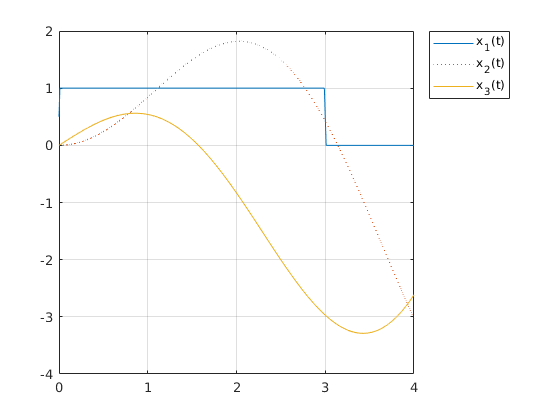


y=x1+x2.*x3;

plot(t,x1,t,x2,':', t, x3, '-')
legend('x_1(t)', 'x_2(t)', 'x_3(t)', 'Location','bestoutside')
grid on

#### SIMO - Single-Input Multiple-Output 

c) Suponha que um sistema SIMO S  é descrito pelas relações  $y_1 \left(t\right)=x_1^2 \left(t\right)$e $y_2 \left(t\right)=1-3x_1 \left(t\right)$. Compute e plot a saída do sistema se o sinal de entrada é dado por $x_1 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

t=0:0.01:4;
x1=t.*cos(t);
y1 = x1.^2;
y2 =1-3.*x1 

y2 =     1.0000    0.9700    0.9400    0.9100    0.8801    0.8502    0.8203    0.7905    0.7608    0.7311    0.7015    0.6720    0.6426    0.6133    0.5841    0.5551    0.5261    0.4974    0.4687    0.4403    0.4120    0.3838    0.3559    0.3282    0.3006    0.2733    0.2462    0.2193    0.1927    0.1663    0.1402    0.1143    0.0887    0.0634    0.0384    0.0137   -0.0108   -0.0349   -0.0587   -0.0821   -0.1053   -0.1281   -0.1505   -0.1726   -0.1943   -0.2156   -0.2366   -0.2571   -0.2773   -0.2970


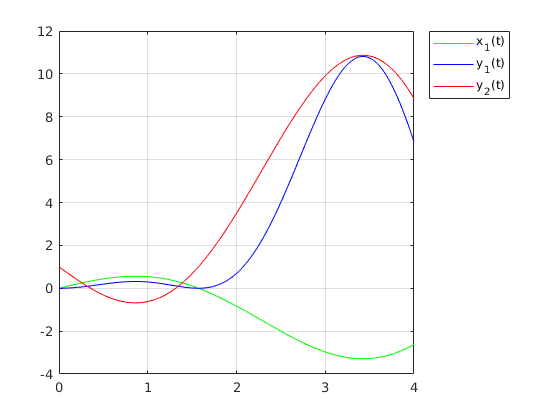

plot(t, x1,'g', t, y1,'b', t, y2, 'r' )
legend('x_1(t)', 'y_1(t)', 'y_2(t)', 'Location','bestoutside')
grid on

#### MIMO - Multiple-Input Multiple-Output 

d) Suponha que um sistema MIMO S  é descrito pelas relações de entrada saída $y_1 \left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)$ e $y_2 \left(t\right)=x_1 \left(t\right)-x_2 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)$, $x_2 \left(t\right)=0\ldotp 5u\left(t-1\right)$, $0\le t\le 4$.

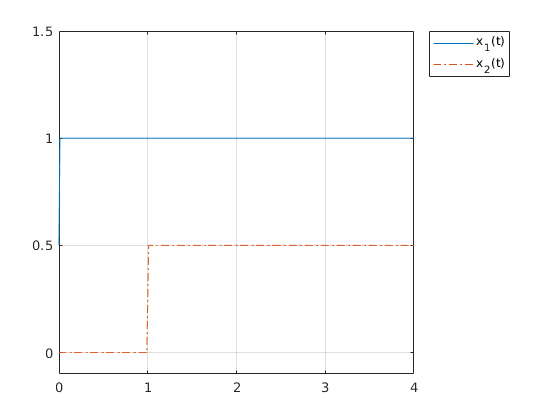

t=0:0.01:4;
x1=heaviside(t);
x2=0.5*heaviside(t-1);
y1 = x1+x2;
y2=x1-x2;
plot (t, x1, t, x2, '-.')
grid on
ylim([-0.1 1.5])
legend('x_1(t)', 'x_2(t)', 'Location','bestoutside')
grid on

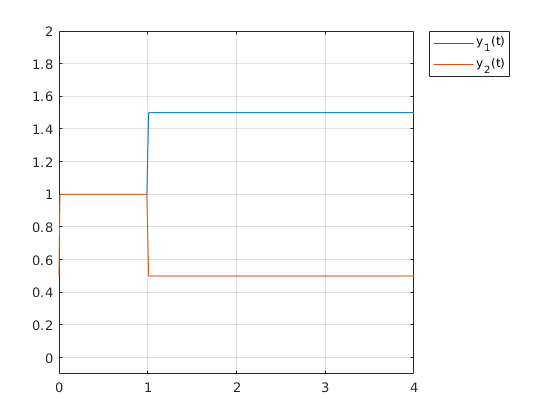


plot (t, y1, t, y2)
legend('y_1(t)', 'y_2(t)', 'Location','bestoutside')
grid on
ylim([-0.1 2])

### Propriedades de sistemas

#### Causal e não causal

e) Suponha que o sistema S1 é descrito pela relação de entrada saída $y_1 \left(t\right)=x\left(t+1\right)$enquanto que do sistema S2 é dada por $y_2 \left(t\right)=x\left(t-1\right)$. Considerando que o sinal de entrada é $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$. Determine se os dois sistemas são causais.

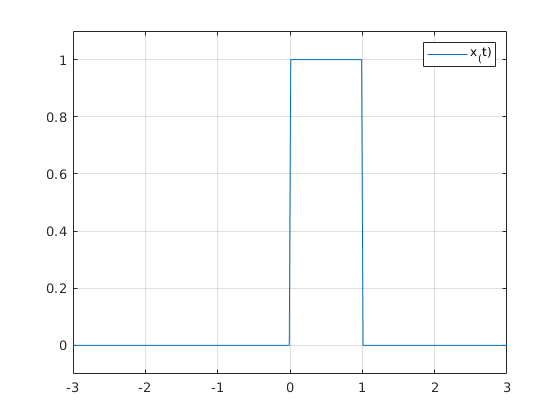

t=-3:0.01:3;
x=heaviside(t)-heaviside(t-1);
plot (t, x)
grid on
ylim([-0.1 1.1])
legend('x_(t)')

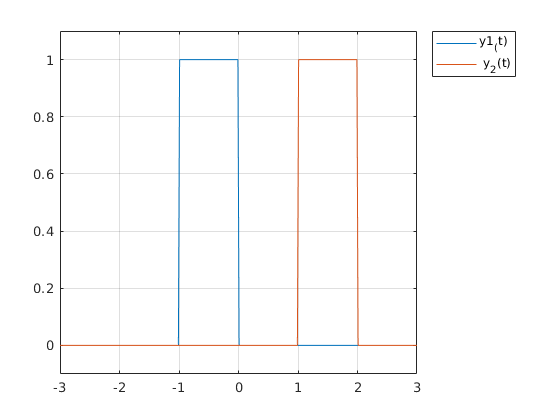

y1= heaviside(t+1)-heaviside((t+1)-1);
y2= heaviside(t-1)-heaviside((t-1)-1);
plot(t, y1, t, y2)
grid on
ylim([-0.1 1.1])
legend('y1_(t)', ' y_2(t)', 'Location','bestoutside')

#### Estático (sem memória) e dinâmico (com memória)

f) Usando o sinal de entrada $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$, determine se os sistemas descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_2 \left(t\right)=x\left(t\right)+x\left(t-1\right)$ são estático ou dinâmico.

t=-3:0.01:3;
x=heaviside(t)-heaviside(t-1);
plot (t, x)
grid on
ylim([-0.1 1.1])
legend('x_(t)')

y1=3.*x;
%y2= x(t)+x(t-1)
%[u(t)- u(t-1)] + [u(t-1)- u(t-2)]
%y2=u(t) - u (t-2)
y2=heaviside(t) - heaviside(t-2)

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%plot(t, x, '--', t, y1, )
grid on
legend('x_(t)', ' y_2(t)', 'Location','bestoutside')

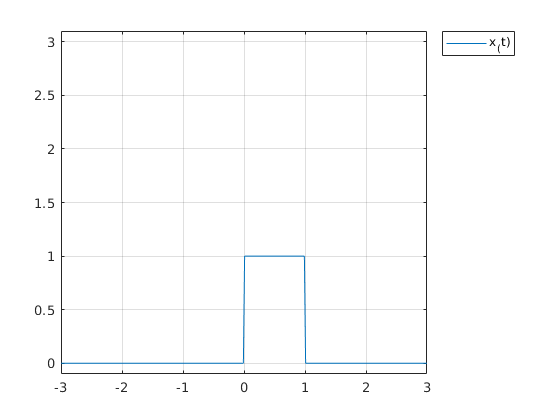

ylim([-0.1 3.1])

#### Linear e não linear


$$S\left\lbrace a_1 {\;x}_1 \left(t\right)+a_2 {\;x}_2 \left(t\right)\right\rbrace =a_1 S\left\lbrace x_1 \left(t\right)\right\rbrace \;+a_{2\;} S\left\lbrace x_2 \left(t\right)\right\rbrace$$


A resposta de um sistema linear para uma entrada que é a combinação linear de dois sinais corresponde a uma combinação linear das respostas do sistema para cada uma destes sinais de entrada. (Princípio da superposição = aditividade + homogenidade).

g) Dado $x_1 \left(t\right)=u\left(t\right)-u\left(t-1\right)$ e $x_2 \left(t\right)=u\left(t\right)-u\left(t-2\right)$ sejam considerados sinais de netrada para os sistemas descritos pelas seguintes relações $y\left(t\right)=2x\left(t\right)$ e $z\left(t\right)=x^2 \left(t\right)$, $-3\le t\le 3$. Determine se a propriedade de linearidade é válida para estes dois sistemas.

Solução: adotando os escalares $a_1 =2$ e $a_2 =3$

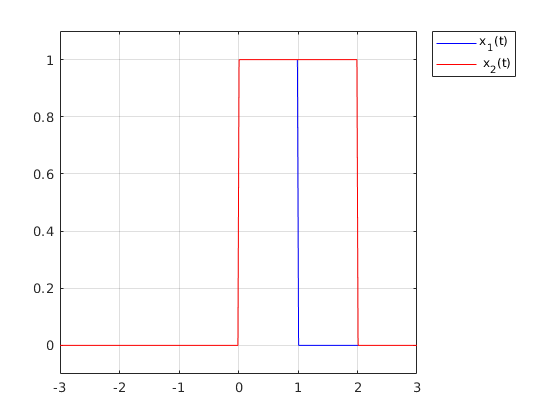

t=-3:0.01:3;
x1=heaviside(t)- heaviside(t-1);
x2=heaviside(t)- heaviside(t-2);

figure 
plot(t, x1, 'b', t ,x2,'r')
grid on 
ylim([-0.1 1.1])
legend('x_1(t)', ' x_2(t)', 'Location','bestoutside')

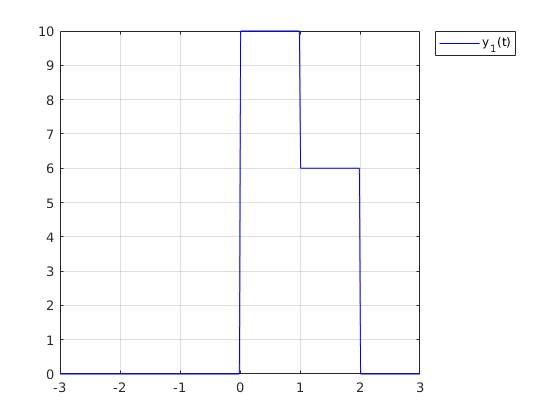

% sistema 1
a1=2;
a2=3;

%x(t)=a1
s=a1*x1+a2*x2;
ys = 2*s;
plot (t, ys, 'b')
grid on
legend('y_1(t)', 'Location','bestoutside')

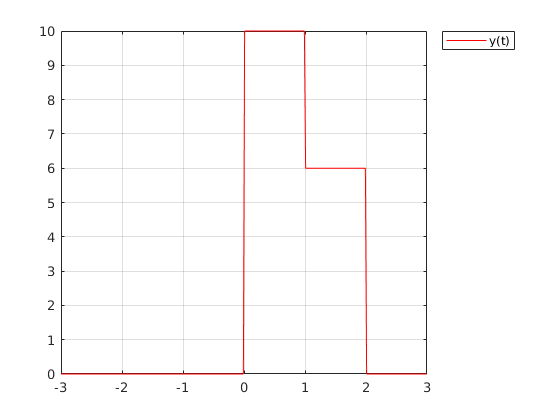

y1=2*x1;
y2=2*x2;
ys2 = a1*y1+a2*y2;
plot (t, ys2, 'r')
grid on
legend('y(t)', 'Location','bestoutside')

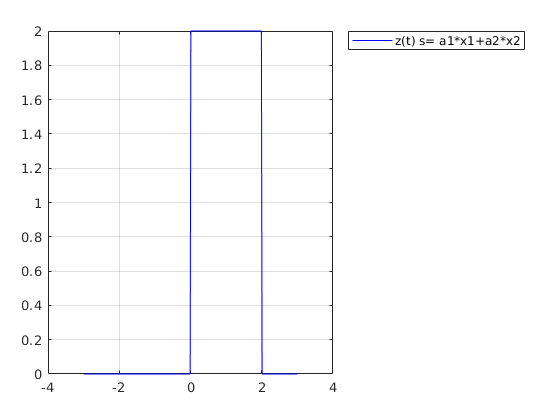

% Sistema 2 -> y(t)=x(t)^2
% s= a1*x1+a2*x2
z=s.^2;
plot (t,y2, 'b')
grid on
legend('z(t) s= a1*x1+a2*x2', 'Location','bestoutside')

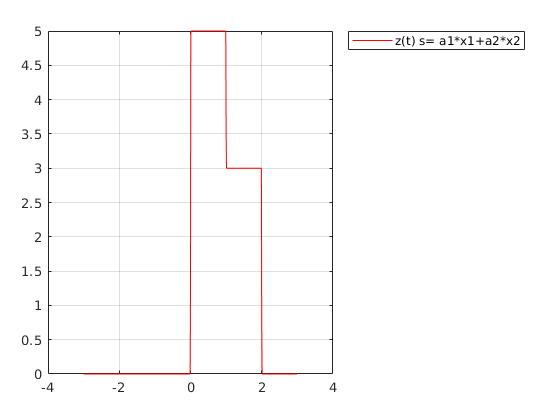

z1=x1.^2;
z2=x2.^2;
zs2=a1*z1+a2*z2;
plot (t, zs2, 'r')
grid on
legend('z(t) s= a1*x1+a2*x2', 'Location','bestoutside')

#### Invariante no tempo e variante no tempo

Se $y\left(t\right)$é a resposta de um sistema invariante no tempo para uma entrada $x\left(t\right)$, então a resposta do sistema para um sinal de entrada $x\left(t-t_0 \right)$é $y\left(t-t_0 \right)$.


$$y\left(t-t_0 \right)=S\left\lbrace x\left(t-t_0 \right)\right\rbrace$$


h) Suponha que a resposta de um sistema S para um sinal de entrada $x\left(t\right)$é $y\left(t\right)={t\;e}^{-t} x\left(t\right)$. Determine se este sistema é invariante no tempo para uma entrada $x\left(t\right)=u\left(t\right)-u\left(t-5\right)$, $-3\le t\le 10$.

        1. Avaliar $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$

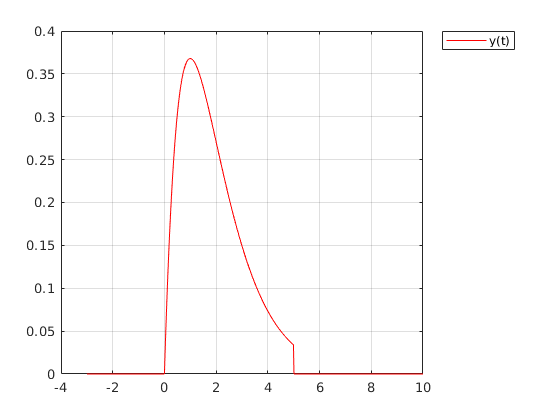

t=-3:0.01:10;
x=heaviside(t)-heaviside(t-5);
y=t.*exp(-t).*x;
figure
plot (t , y ,'r')
grid on
legend('y(t)', 'Location','bestoutside')

        2. Obter $y\left(t-t_0 \right)$, $t_0 =3$

plot (t+3, y)
grid on
hold on 


        3. Obter $S\left\lbrace x\left(t-t_0 \right)\right\rbrace$, $t_0 =3$ e comparar com o passo 2.

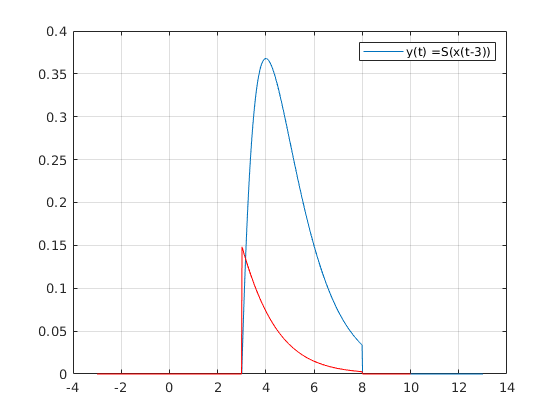

t=-3:0.01:10;
x=heaviside(t-3)-heaviside(t-5-3);
y=t.*exp(-t).*x;
plot (t , y ,'r')
grid on
legend('y(t) =S(x(t-3))')

#### Estável e instável

BIBO - *Bounded-Input Bounded Output*

Para um pequeno sinal aplicado na entrada a resposta do sistema também é pequena e não diverge. Ou seja, se um dado número positivo existe $M<\infty$, tal que $\left|x\left(t\right)\right|\le M$. O sistema é estável se $\forall t\in \Re$ um número positivo $N<\infty$, tal que $\left|y\left(t\right)\right|\le N$.

i) Suponha que um sinal de entrada $x\left(t\right)=\cos \left(2\pi \;t\right)$é aplicado a dois sistemas descritos pela relação de entrada saída $y_1 \left(t\right)=x^2 \left(t\right)$e $y_2 \left(t\right)=t\;x\left(t\right)$, $0\le t\le 10$. . Determine se estes sistemas são estáveis.

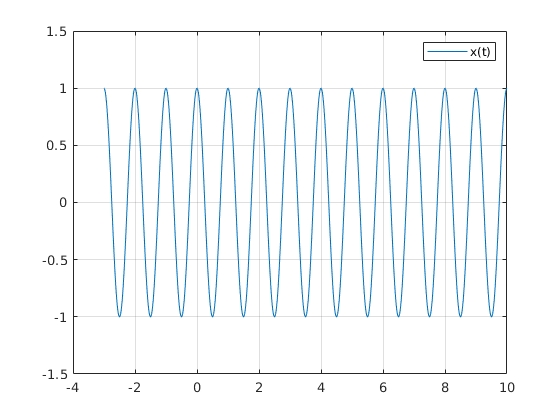

t=-3:0.01:10;
x= cos (2*pi*t);
figure
plot(t,x)
grid on
ylim([-1.5 1.5])
legend('x(t)')

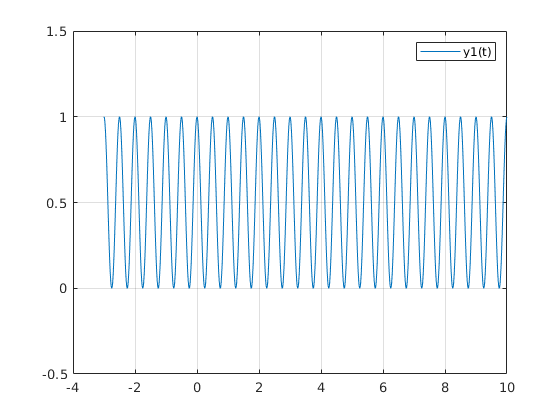

% Avaliando se o sistema 1 é estavel ou instavel
y1 = x.^2;
plot(t, y1)
grid on
ylim([-0.5 1.5])
legend('y1(t)')

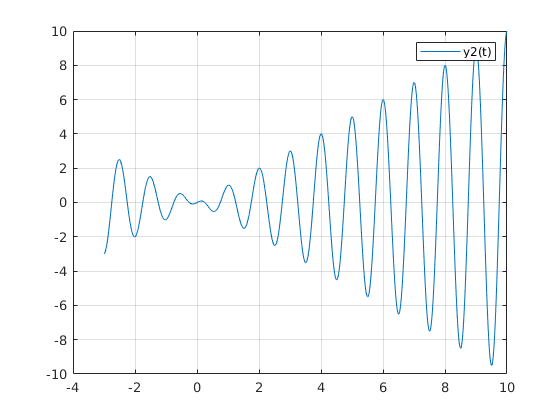

y2=t.*x;
plot(t, y2)
grid on
legend('y2(t)')

#### Invertível e não invertível

Um sistema é invertível se um sinal de entrada $x\left(t\right)$que é aplicado ao sistema pode ser derivado a partir da resposta do sistema $y\left(t\right)$. Ou seja, um sistema é invertível se a relação entrada saída $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$é uma para uma, isto é, diferentes valores de entrada correspondem a distintos valores de saída.

j) Determine se os sistemas S1 e S2 descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_1 \left(t\right)=x^2 \left(t\right)$, respectivamente, são invertíveis. Considere $x\left(t\right)=2\;t$, $-2\le t\le 2\ldotp$

t=-2:2;
x= 2.*t;
y1 = 3.*x;
y2 = x.^2;



- Sistema inverso

            
$$z\left(t\right)=S^{-1} \left\lbrace y\left(t\right)\right\rbrace$$


z1=1/3*y1

z1 =     -4    -2     0     2     4


z2=sqrt(y2)

z2 =      4     2     0     2     4
